% Define parameters
a = 0.0015;    % Value of 'a'
b = 0.001;    % Value of 'b'

% Define control input function (example: step function)
u = @(t) 1 * (t >= 1);  % Step function at t = 1

% Define the differential equation function
f = @(t, x) -a * (x - xr) + b * u(t);

% Initial condition
xr = 100;   % Reference value
x0 = 210;   % Initial value of x

% Time span
tspan = 0:0.1:10000;

% Solve the differential equation
[t, x] = ode45(f, tspan, x0);

% Model_4_50
% Define parameters
k = 2.2789;    % Value of 'a'
t1 = 1369.3;    % Value of 'b'

% Define control input function (example: step function)
u = @(t) 1 * (t >= 1);  % Step function at t = 1

% Define the differential equation function
f1 = @(t, x) -1/t1 *(x-xr) + k/t1 * u(t);

% Initial condition
xr = 100;   % Reference value
x0 = 210;   % Initial value of x

% Time span
tspan = 0:15:10000;

% Solve the differential equation
[t1, x1] = ode45(f1, tspan, x0);

% Model_4_100
% Define parameters
k_4_100 = 1.5614;    % Value of 'a'
tau_4_100 = 3293.2;    % Value of 'b'

% Define control input function (example: step function)
u = @(t) 1 * (t >= 1);  % Step function at t = 1

% Define the differential equation function
f2 = @(t, x) -1/tau_4_100 *(x-xr) + k_4_100/tau_4_100 * u(t);

% Initial condition
xr = 100;   % Reference value
x0 = 210;   % Initial value of x

% Time span
tspan = 0:0.1:10000;

% Solve the differential equation
[t2, x2] = ode45(f2, tspan, x0);

% Model_8_50
% Define parameters
k_8_50 = 2.667;    % Value of 'a'
tau_8_50 = 1331.4;    % Value of 'b'

% Define control input function (example: step function)
u = @(t) 1 * (t >= 1);  % Step function at t = 1

% Define the differential equation function
f3 = @(t, x) -1/tau_8_50 *(x-xr) + k_8_50/tau_8_50 * u(t);

% Initial condition
xr = 100;   % Reference value
x0 = 210;   % Initial value of x

% Time span
tspan = 0:0.1:10000;

% Solve the differential equation
[t3, x3] = ode45(f3, tspan, x0);

% Model_8_100
% Define parameters
k_8_100 = 1.4178;    % Value of 'a'
tau_8_100 = 1883.6;    % Value of 'b'

% Define control input function (example: step function)
u = @(t) 1 * (t >= 1);  % Step function at t = 1

% Define the differential equation function
f4 = @(t, x) -1/tau_8_100 *(x-xr) + k_8_100/tau_8_100 * u(t);

% Initial condition
xr = 100;   % Reference value
x0 = 210;   % Initial value of x

% Time span
tspan = 0:0.1:10000;

% Solve the differential equation
[t4, x4] = ode45(f4, tspan, x0);

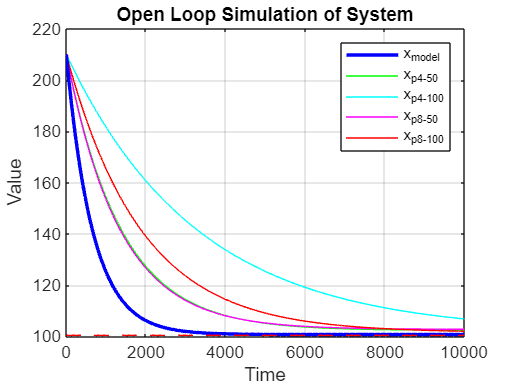

% Plot results
figure;
plot(t, x, 'b', 'LineWidth', 2);
hold on
plot(t1,x1, 'g-')
hold on
plot(t2,x2, 'c-')
hold on
plot(t3,x3, 'm-')
hold on
plot(t4,x4, 'r-')
hold on
plot(t, x, 'b', 'LineWidth', 2);
hold on
plot(t, xr*ones(size(t)), 'r--', 'LineWidth', 2);
hold off;
xlabel('Time');
ylabel('Value');
title('Open Loop Simulation of System');
legend('x_{model}', 'x_{p4-{50}}','x_{p4-{100}}','x_{p8-{50}}','x_{p8-{100}}');
grid on;